# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 12-Oct-2021 00:52:09

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Лист1";
opts.DataRange = "R2:S30";

% Specify column names and types
opts.VariableNames = ["V_4", "I_2"];
opts.VariableTypes = ["double", "double"];

% Import the data
Untitled1 = readtable("C:\Users\Marina\Documents\Без имени 1.xlsx", opts, "UseExcel", false)

Untitled1 = 29×2 table
     V_4      I_2 
    _____    _____

    24.96    40.61
    22.06    39.33
    19.01    37.95
    15.91     36.4
    12.93    34.72
    10.01    31.74
        8    28.52
     5.99    23.95
     4.08    18.19
        2     10.4
     0.79     5.41
      0.5     4.15
      0.3     3.39
     0.25     3.11
     0.16     2.78
    -0.16     1.94


hold on;
grid on
grid("minor")
V_4 = [  
     24.96
     22.06
     19.01
     15.91
     12.93
     10.01
         8
      5.99
      4.08
         2
      0.79
       0.5
       0.3
      0.25
      0.16
     -0.16
     -0.33
     -0.53
     -0.85
     -2.04
     -4.08
        -6
      -8.2
     -9.98
    -13.09
    -16.01
    -19.05
    -21.95
    -25.02

]

V_4 =    24.9600
   22.0600
   19.0100
   15.9100
   12.9300
   10.0100
    8.0000
    5.9900
    4.0800
    2.0000



A_4 = [  
     40.61
     39.33
     37.95
      36.4
     34.72
     31.74
     28.52
     23.95
     18.19
      10.4
      5.41
      4.15
      3.39
      3.11
      2.78
      1.94
      1.25
      0.41
      -0.9
     -5.82
    -13.32
    -18.98
    -23.72
    -26.39
    -29.29
    -30.79
    -31.97
    -33.07
    -34.28

]

A_4 =    40.6100
   39.3300
   37.9500
   36.4000
   34.7200
   31.7400
   28.5200
   23.9500
   18.1900
   10.4000


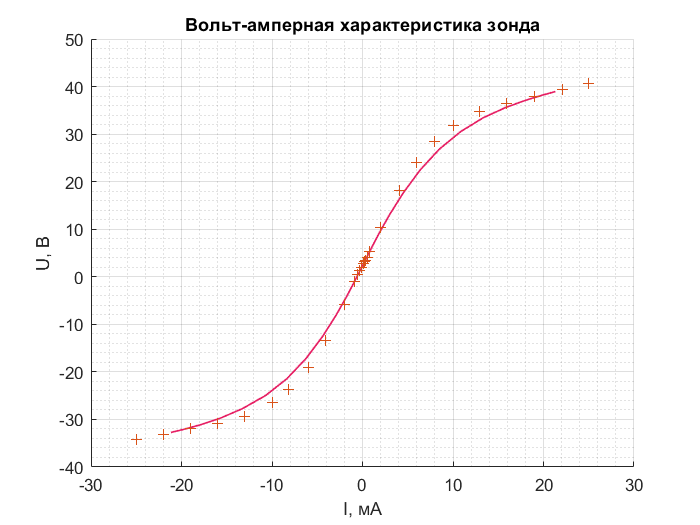


V_4_S = smoothdata(V_4,'gaussian',10);
A_4_S = smoothdata(A_4,'gaussian',10);
plot(V_4_S,A_4_S,"LineWidth",1,"Color",[0.9 0.108 0.38]);
scatter(V_4, A_4, "Marker","+","MarkerEdgeColor","flat");
title("Вольт-амперная характеристика зонда")
xlabel('I, мА')
ylabel('U, В')

## Clear temporary variables

clear opts